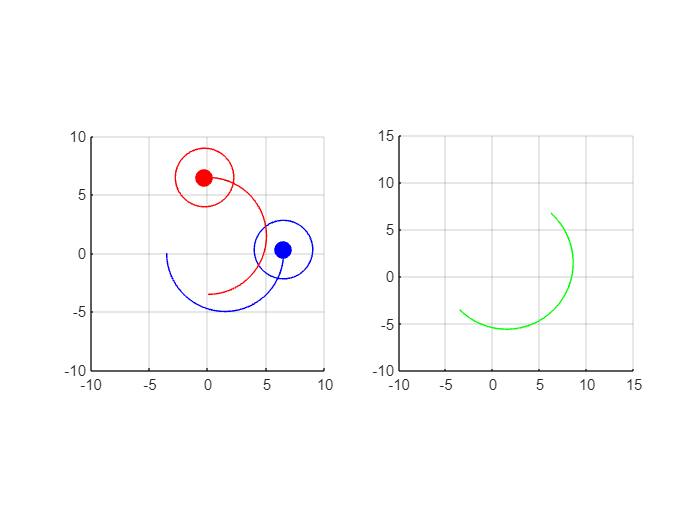

% USE OF THE NOTEBOOK
% This notebook is a simulation of air-conflict-resolution problem seen
% from a relative system.
% This code should work for every value of v, omega, phi with the
% assumption that linear and angular velocity are the same between the
% aircraft. Remember to check/change equation in state q2 ( solution of
% differential equation ).
% ENSURE that hyperparameters ( velocities, times and relative velocity) are correct
% CHECK initial position: seeing the simulation at time 0, we can infere if
% the relative position of red aircraft respect to the blue one is correct
% according to relative simulation
% NOTE: simulation doesn't work for negative omega but is is possibile see
% anyway what will happend if the rotate with a negative omega ( if there
% will be a collision or not )

% Points in which the simulation have been check are
% P1 = [-3.54; 0];  / [-5, 0]   / [0, 0]    / [-7.7, 0]
% P2 = [0; -3.54];  / [0, 0 ]   / [0, -5]   / [0, -7.7]
% omega =   1       / 1         / -1        / 1
% omega2 = 1        / 1         / -1        / 1

% cases: base_case / other example / base with negative omega / collision

% Hyperparameters
r = 2.5;         % Radius of the circles
v = 5;           % linear velocity
omega = 1;       % Angular velocity
phi = pi/2;      % direction

v1 = v;             % linear velocity of blue aircraft
v2 = v;             % linear velocity of red aircraft
omega1 = omega;     % angular velocity of blue aircraft
omega2 = omega;     % angular velocity of red aircraft

r_turn = v/omega;      % Radius of curvature

T = abs(pi / omega);  % Duration of the simulation for half a circle
dt = 0.1;             % Time step

% Initial points
% should be taken from 'air-conflict-resolution' script
% to understand correcly the point
P1 = [-3.54; 0];    % Blue aircraft
P2 = [0; -3.54];    % Red aircraft

% Centers of the circles
center1 = P1 + [r_turn; 0]; % Center for the blue aircraft's protected zone
center2 = P2 + [0; r_turn]; % Center for the red aircraft's protected zone

% Setup the figure for plotting
figure;
subplot(1, 2, 1); 
hold on;
axis equal;
xlim([-10 10]);
ylim([-10 10]);
grid on;

% Generate the circle points
theta = linspace(0, 2*pi, 100); % discretizing cirlcle
x_circle = r * cos(theta);
y_circle = r * sin(theta);

% creating object
a1 = plot(P1(1), P1(2), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b'); % Blue aircraft
a2 = plot(P2(1), P2(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % Red aircraft
c1 = plot(P1(1) + x_circle, P1(2) + y_circle, 'b'); % protected zone for blue aircraft
c2 = plot(P2(1) + x_circle, P2(2) + y_circle, 'r'); % protected zone for red aircraft

% where to store trajectory done by aircrafts
traj1_x = P1(1);
traj1_y = P1(2);
traj2_x = P2(1);
traj2_y = P2(2);

% Plot the initial trajectory
t1 = plot(traj1_x, traj1_y, 'b'); % Trajectory for blue aircraft
t2 = plot(traj2_x, traj2_y, 'r'); % Trajectory for red aircraft

% Initial angles
angle1 = 0;
angle2 = phi;    % angle of red aircraft respect to blue one

% Plotting trajectory
subplot(1, 2, 2); 
hold on;
axis equal;
xlim([-10 15]);
ylim([-10 15]);
grid on;

% Rotation matrix for -pi/2
% NOTE: seen from blue aircraft, if x-axis must rotate down
% it is not pi/2 ( so positive ) because in a relative system, when the
% blue rotate, in the object moving to left side. Here we are in global
% reference frame and the correct rotation is -pi/2
theta = -pi/2; 
rot = [cos(theta), -sin(theta); sin(theta), cos(theta)];

% Calculate initial relative position
rel_x = P2(1) - P1(1);
rel_y = P2(2) - P1(2);

% Rotate the initial relative position
rotated_traj = rot * [rel_x; rel_y];
rel_traj_x = rotated_traj(1);
rel_traj_y = rotated_traj(2);

% Plot the initial relative trajectory
t_rel = plot(rel_traj_x, rel_traj_y, 'g'); % Relative trajectory for red point w.r.t blue point

for t = 0:ceil(T/dt)

    % calculating angles
    angle1 = -omega1 * (t * dt); 
    angle2 = -phi - omega2 * (t * dt); 

    % update position of aircrafts
    P1 = center1 + r_turn * [-cos(angle1); sin(angle1)];
    P2 = center2 + r_turn * [-cos(angle2); sin(angle2)];

    % updating plots
    set(a1, 'XData', P1(1), 'YData', P1(2));
    set(a2, 'XData', P2(1), 'YData', P2(2));

    set(c1, 'XData', P1(1) + x_circle, 'YData', P1(2) + y_circle);
    set(c2, 'XData', P2(1) + x_circle, 'YData', P2(2) + y_circle);

    % updating trajectory
    traj1_x = [traj1_x, P1(1)];
    traj1_y = [traj1_y, P1(2)];
    traj2_x = [traj2_x, P2(1)];
    traj2_y = [traj2_y, P2(2)];
    
    % updating relative position
    rel_x = P2(1) - P1(1);
    rel_y = P2(2) - P1(2);
    
    % Rotated for obtain right relative position
    rotated_traj = rot * [rel_x; rel_y];
    rel_x_rotated = rotated_traj(1);
    rel_y_rotated = rotated_traj(2);

    % relative trajectory update
    rel_traj_x = [rel_traj_x, rel_x_rotated];
    rel_traj_y = [rel_traj_y, rel_y_rotated];

    % updating plots
    set(t1, 'XData', traj1_x, 'YData', traj1_y);
    set(t2, 'XData', traj2_x, 'YData', traj2_y);
    set(t_rel, 'XData', rel_traj_x, 'YData', rel_traj_y);

    pause(dt);
end

subplot(1, 2, 1);

hold off;